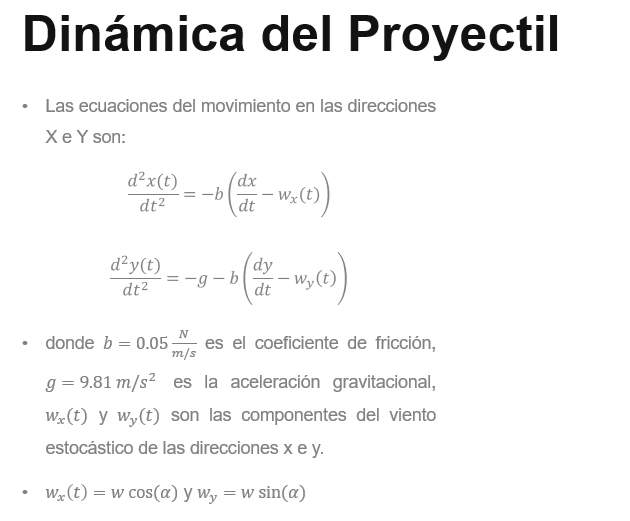

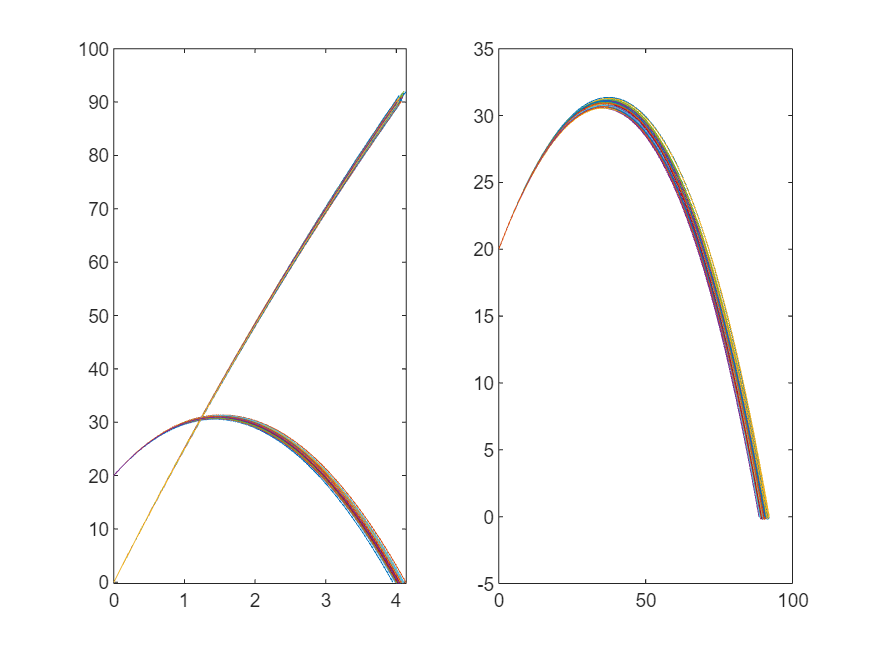

clear all
close all


% Número de muestras
num_samples = 100;


% Configuración de la simulación
t = 0:0.01:20;  % Tiempo de simulación

% Prealocar espacio para los resultados
impacto = zeros(num_samples, 1);
altura_maxima = zeros(num_samples,1);
velocidad_imapcto = zeros(num_samples,2);
% Simular cada sistema
figure(1)

for i = 1:num_samples

    % Ejecutar la simulación
    simOut = sim('t8_videoclase3_beta', 'StopTime', num2str(10));

    t = simOut.tout;
    % Guardar el resultado final (por ejemplo, el desplazamiento en t=10)
    impacto(i) = simOut.y(end, 1);
    velocidad_imapcto(i,:) = simOut.ydot(end,:);
    altura_maxima(i) = max(simOut.y(:, 2));

    subplot(121)
    plot(t,simOut.y); hold on
    subplot(122)
    plot(simOut.y(:,1),simOut.y(:,2)); hold on
    
end

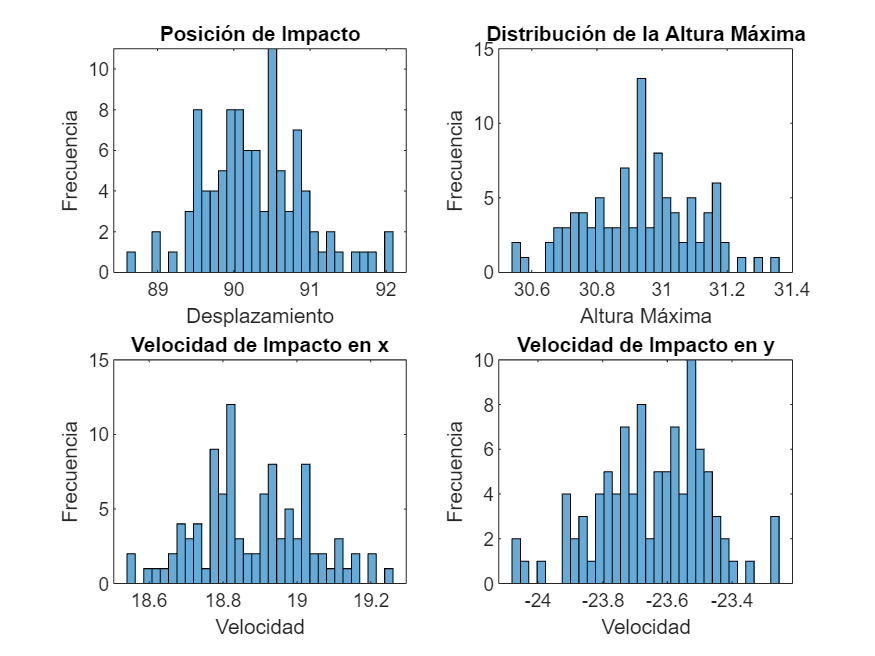


% Análisis de los resultados
media_desplazamiento = mean(impacto);
std_desplazamiento = std(impacto);

media_velocidad = mean(velocidad_imapcto);
std_velocidad = std(velocidad_imapcto);

media_alturaMaxima = mean(altura_maxima);
std_alturaMaxima = std(altura_maxima);

% Visualización de los resultados
figure;
bins = 32;
subplot(221)
histogram(impacto(:,1), bins);
title('Posición de Impacto');
xlabel('Desplazamiento');
ylabel('Frecuencia');
subplot(222)
histogram(altura_maxima, bins);
title('Distribución de la Altura Máxima');
xlabel('Altura Máxima');
ylabel('Frecuencia');
subplot(223)
histogram(velocidad_imapcto(:,1), bins);
title('Velocidad de Impacto en x');
xlabel('Velocidad');
ylabel('Frecuencia');
subplot(224)
histogram(velocidad_imapcto(:,2), bins);
title('Velocidad de Impacto en y');
xlabel('Velocidad');
ylabel('Frecuencia');